clear;

rng(100)
m0 = [0,0];
P0 = 2*eye(2);

A = [0 1;
    0 0];
B = [0;1];
Gamma = [0;1];
C = [1 0];
Wtilde = 1;
Vtilde = 0.005;
CTsys = ss(A,B,C,0);

deltaT = 0.1

deltaT = 0.1000


DTsys = c2d(CTsys,deltaT,'zoh');
F = DTsys.a;
G = DTsys.b;
H = DTsys.c;

M = deltaT*[-A, Gamma*Wtilde*Gamma';
    zeros(size(A)), A']

M =          0   -0.1000         0         0
         0         0         0    0.1000
         0         0         0         0
         0         0    0.1000         0


matrexp_M = expm(M)

matrexp_M =     1.0000   -0.1000   -0.0002   -0.0050
         0    1.0000    0.0050    0.1000
         0         0    1.0000         0
         0         0    0.1000    1.0000


invFQblock = matrexp_M(1:2,3:4);
Qtrue = F*invFQblock

Qtrue =     0.0003    0.0050
    0.0050    0.1000



Rtrue = Vtilde / deltaT

Rtrue = 0.0500


tvec = 0:deltaT:12;
u = 2*cos(0.75*tvec);

Fkf = [1 deltaT;
    0 1];
Gkf = [0.5*deltaT^2;
    deltaT];
Hkf = [1 0];

Qkf = diag([5e-3 1e-3 ]);
Rkf = Rtrue;
Nsimruns = 50

Nsimruns = 50

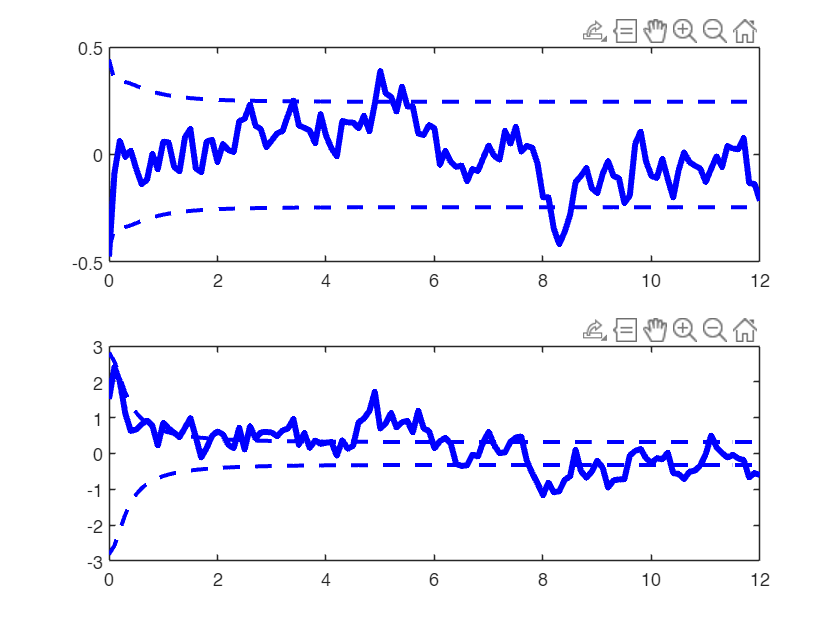

NEESsamps = zeros(Nsimruns,length(tvec));
NISsamps = zeros(Nsimruns,length(tvec));
for ss=1:Nsimruns
    xk_truehist = zeros(2,length(tvec));
    ykhist = zeros(1,length(tvec));
    xk = mvnrnd(m0,P0);
    for jj=1:length(tvec)
        wk = mvnrnd(zeros(1,2),Qtrue);
        xkp1 = F*xk' + G*u(jj) + wk';
        vkp1 = mvnrnd(zeros(1,1),Rtrue)';
        ykp1 = H*xkp1 + vkp1;
        xk_truehist(:,jj) = xkp1;
        ykhist(:,jj) = ykp1;
        xk = xkp1';
    end

    mk = m0;
    Pk = P0;
    mk_filt_hist = zeros(2,length(tvec));
    Pk_filt_hist = zeros(2,2,length(tvec));
    innovk_hist = zeros(1,length(tvec));
    Pyyk_hist = zeros(1,1,length(tvec)); 
    NEESsshist = zeros(1,length(tvec));
    NISsshist = zeros(1,length(tvec));
    for jj=1:length(tvec)

        mkp1_minus = F*mk' + G*u(jj);
        Pkp1_minus = F*Pk*F' + Qkf;

        Pyykp1 = H*Pkp1_minus*H' + Rtrue;
        Pyykp1 = 0.5*(Pyykp1 + Pyykp1');
        Kkp1 = Pkp1_minus*H'/(H*Pkp1_minus*H' + Rtrue);

        ykp1_report = ykhist(:,jj);
        ykp1_pred = H*mkp1_minus;
        innov_kp1 = ykp1_report - ykp1_pred;
        mkp1_plus = mkp1_minus + Kkp1*innov_kp1;
        Pkp1_plus = (eye(2) - Kkp1*H)*Pkp1_minus;
        mk = mkp1_plus';
        mk_filt_hist(:,jj) = mkp1_plus;
        Pk = Pkp1_plus;
        Pk_filt_hist(:,:,jj)= Pkp1_plus;
        innovk_hist(:,jj) = innov_kp1;

        invPkp1 = inv(Pkp1_plus);
        invPyykp1 = inv(Pyykp1);
        NEESsshist(jj) = ...
            (xk_truehist(:,jj) - mkp1_plus)'*invPkp1*(xk_truehist(:,jj) - mkp1_plus);
        NISsshist(jj) = innov_kp1'*invPyykp1*innov_kp1;
    end
    NEESsamps(ss,:) = NEESsshist;
    NISsamps(ss,:) = NISsshist;

    figure(5),
    clf
    subplot(211)
    plot(tvec,xk_truehist(1,:)-mk_filt_hist(1,:),'b','LineWidth',3), hold on
    plot(tvec,2*sqrt(squeeze(Pk_filt_hist(1,1,:))'),'b--','LineWidth',2)
    plot(tvec,-2*sqrt(squeeze(Pk_filt_hist(1,1,:))'),'b--','LineWidth',2)
    subplot(212)
    plot(tvec,xk_truehist(2,:)-mk_filt_hist(2,:),'b','LineWidth',3), hold on
    plot(tvec,2*sqrt(squeeze(Pk_filt_hist(2,2,:))'),'b--','LineWidth',2)
    plot(tvec,-2*sqrt(squeeze(Pk_filt_hist(2,2,:))'),'b--','LineWidth',2)
end


epsNEESbar = mean(NEESsamps,1);
alphaNEES = 0.05; 
Nnx = Nsimruns*length(Fkf);

r1x = chi2inv(alphaNEES/2, Nnx )./ Nsimruns

r1x = 1.4844

r2x = chi2inv(1-alphaNEES/2, Nnx )./ Nsimruns

r2x = 2.5912

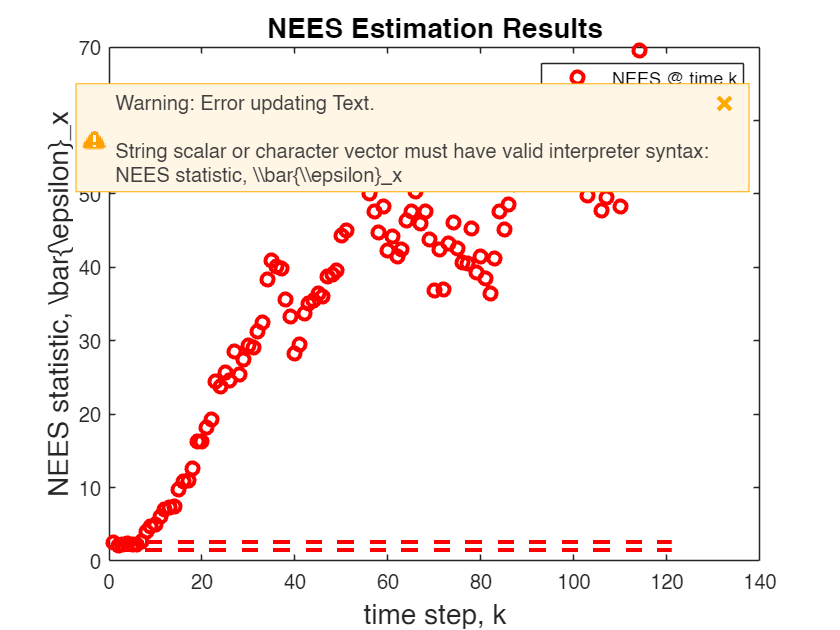

figure(80)
plot(epsNEESbar,'ro','MarkerSize',6,'LineWidth',2),hold on
plot(r1x*ones(size(epsNEESbar)),'r--','LineWidth',2)
plot(r2x*ones(size(epsNEESbar)),'r--','LineWidth',2)
ylabel('NEES statistic, \bar{\epsilon}_x','FontSize',14)
xlabel('time step, k','FontSize',14)
title('NEES Estimation Results','FontSize',14)
legend('NEES @ time k', 'r_1 bound', 'r_2 bound')


epsNISbar = mean(NISsamps,1);
alphaNIS = 0.05;
Nny = Nsimruns*size(H,1);

r1y = chi2inv(alphaNIS/2, Nny )./ Nsimruns

r1y = 0.6471

r2y = chi2inv(1-alphaNIS/2, Nny )./ Nsimruns

r2y = 1.4284

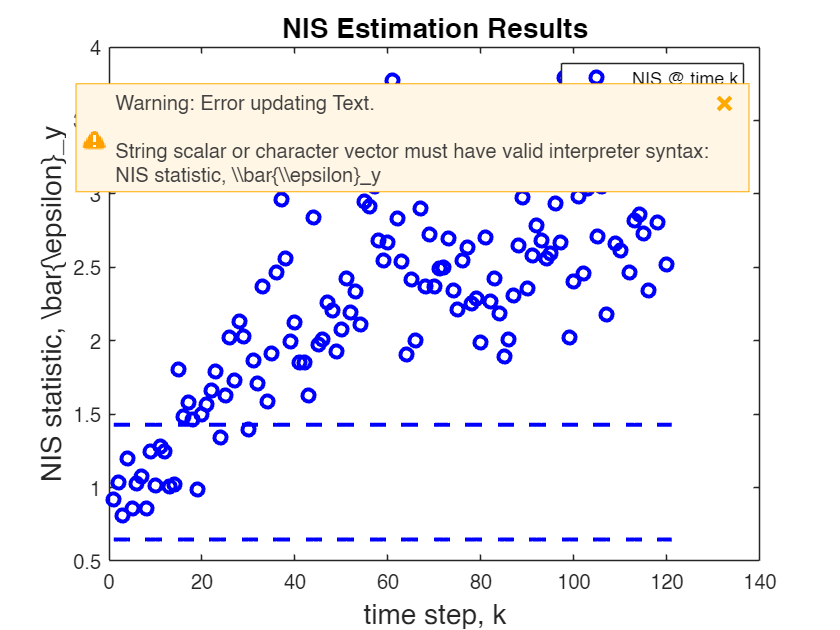

figure(90)
plot(epsNISbar,'bo','MarkerSize',6,'LineWidth',2),hold on
plot(r1y*ones(size(epsNISbar)),'b--','LineWidth',2)
plot(r2y*ones(size(epsNISbar)),'b--','LineWidth',2)
ylabel('NIS statistic, \bar{\epsilon}_y','FontSize',14)
xlabel('time step, k','FontSize',14)
title('NIS Estimation Results','FontSize',14)
legend('NIS @ time k', 'r_1 bound', 'r_2 bound')